clear;
clc;
close all;

load('dataset.mat');

N=length(data);
theta=3;
lambda=3;
tol=10e-6;

[lambda_newton, i] = newton_raphson_lambda(theta,N,data,lambda,tol)

lambda_newton = 0.5191

i = 0

thetaest = ((1/N)*sum(data.^lambda_newton)).^(1/lambda_newton);

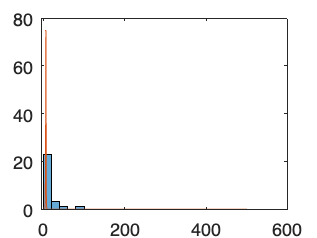

figure;
histogram(data);
hold on;
plot(10*wblpdf(0:0.1:50,lambda_newton,thetaest));
hold off;

dist=KLDiv(data,wblpdf(0:27,lambda_newton,thetaest))

dist = 0

%R-squared (R2)
% fit a linear regression model
mdl = fitlm(data,wblpdf(0:0.1:2.7,lambda_newton,thetaest));

% calculate R-squared
R2 = mdl.Rsquared.Ordinary

R2 = 0.0154

function [lambda, i] = newton_raphson_lambda(theta,N,x,lambda,tol)
% temp=lambda0;
temp=lambda;
o=[];
i = 0;


while i ==0
    
    g = (N/lambda)-(N*log(theta))+sum(log(x))-sum((x./theta).^(lambda).*log(x./theta));
    g1 = (-N/lambda^2)-sum((x./theta).^(lambda).*log(x./theta).^2);
    update=g/(g1);
    lambda=temp-update;
    if abs(lambda - temp) < tol
        break;
    end
    temp=lambda;
end
end

function dist=KLDiv(P,Q)
if size(P,2)~=size(Q,2)
    error('the number of columns in P and Q should be the same');
end

if sum(~isfinite(P(:))) + sum(~isfinite(Q(:)))
   error('the inputs contain non-finite values!') 
end

% normalizing the P and Q
if size(Q,1)==1
    Q = Q ./sum(Q);
    P = P ./repmat(sum(P,2),[1 size(P,2)]);
    temp =  P.*log(P./repmat(Q,[size(P,1) 1]));
    temp(isnan(temp))=0;% resolving the case when P(i)==0
    dist = sum(temp,2);
    
    
elseif size(Q,1)==size(P,1)
    
    Q = Q ./repmat(sum(Q,2),[1 size(Q,2)]);
    P = P ./repmat(sum(P,2),[1 size(P,2)]);
    temp =  P.*log(P./Q);
    temp(isnan(temp))=0; % resolving the case when P(i)==0
    dist = sum(temp,2);
end
end